# Ex06. Introduction to Signals and systems

### s1320112/ Motohisa YAMANO

## 1. Plot 3*3 Charts with Function sinc()

 This assignment involves creating and discussing 3*3 signal charts for the sinc function. For the numerical computation, the discrete time index n from -40 to 40 with an increment of 1. The frequency domain ω is sampled at intervals of 0.1(from -2*pi to 2*pi), and the constant ω_c is set to 2. Change the limited length setting and compare the results output via the "phase()" and "abs()" functions.

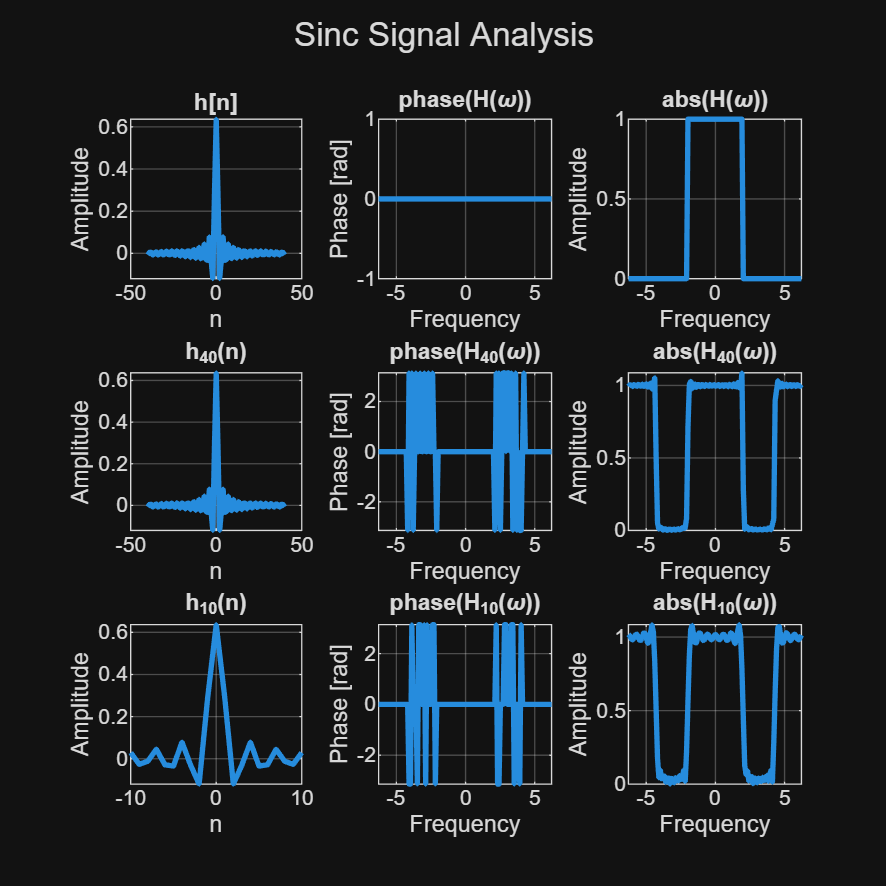

n = -40:1:40;
n10 = -10:1:10;
omega = -2*pi:0.1:2*pi;
omega_c = 2;

h = @(n) (omega_c / pi) .* sinc((omega_c .* n) ./ pi);
H = @(omega) (abs(omega) < omega_c);

H10 = zeros(size(omega));
for i = n10
    H10 = H10 + h(i) .* exp(-1j .* omega .* i);
end

H40 = zeros(size(omega));
for i = n
    H40 = H40 + h(i) .* exp(-1j .* omega .* i); 
end

phase40 = angle(H40);
phase40 = (phase40);
phase10 = angle(H10);
phase10 = (phase10);
figure('Position', [100, 100, 1000, 1000]);

subplot(3, 3, 1);
plot(n, h(n), 'LineWidth', 2);
title('h[n]');
xlabel('n');
ylabel('Amplitude');
grid on;

subplot(3, 3, 2);
plot(omega, phase(H(omega)), 'LineWidth', 2);
title('phase(H(\omega))');
xlabel("Frequency");
ylabel('Phase [rad]');
grid on;

subplot(3, 3, 3);
plot(omega, abs(H(omega)), 'LineWidth', 2);
title('abs(H(\omega))');
xlabel("Frequency");
ylabel('Amplitude');
grid on;

subplot(3, 3, 4);
plot(n, h(n), 'LineWidth', 2);
title('h_{40}(n)');
xlabel("n");
ylabel('Amplitude');
grid on;

subplot(3, 3, 5);
plot(omega, phase40, 'LineWidth', 2);
title('phase(H_{40}(\omega))');
xlabel("Frequency");
ylabel('Phase [rad]');
grid on;

subplot(3, 3, 6);
plot(omega, abs(H40), 'LineWidth', 2);
title('abs(H_{40}(\omega))');
xlabel("Frequency");
ylabel('Amplitude');
grid on;

subplot(3, 3, 7);
plot(n10, h(n10), 'LineWidth', 2);
title('h_{10}(n)');
xlabel("n");
ylabel('Amplitude');
grid on;

subplot(3, 3, 8);
plot(omega, phase10, 'LineWidth', 2);
title('phase(H_{10}(\omega))');
xlabel("Frequency");
ylabel('Phase [rad]');
grid on;

subplot(3, 3, 9);
plot(omega, abs(H10), 'LineWidth', 2);
title('abs(H_{10}(\omega))');
xlabel("Frequency");
ylabel('Amplitude');
grid on;

sgtitle('Sinc Signal Analysis'); 

#### 1.2. Discussion

The figures plotted above show several remarkable trends. First of all, the graphs in the first row describe the ideal behavior of each function (h[n], H(ω)), where abs(H(ω)) exhibits a perfect rectangular shape and phase(H(ω)) is constantly 0 across the entire frequency range.

The figures located below describe the behavior when the impulse response h[n] is truncated to a finite length. Regarding phase(H(ω)) and abs(H(ω)), after applying the DTFT to the finite-length segments, ripples (Gibbs phenomenon) begin to appear near the cutoff frequencies. This tendency is particularly pronounced in abs(H(ω)); the shorter the limited length of the impulse response, the larger the ripples become, failing to maintain the perfect rectangular shape.

## 2. Math Problem

Below is the snapshot of my answer in fill-blank math problem.